# **第三章 BP神经网络**

### 3.1 BP神经网络简介

        如图1所示，上个世纪80年代中期，人工智能技术迎来了第二次发展浪潮。BP神经网络，准确地说，应该称之为前向型神经网络的误差反向传播（Backpropagation, BP）训练算法，在当时引领着整个人工智能领域的发展。其思想甚至一直延伸到人工智能第三次发展浪潮的今天，以卷积神经网络为代表的许多深度神经网络训练算法本质上采用的也是误差反向传播策略。

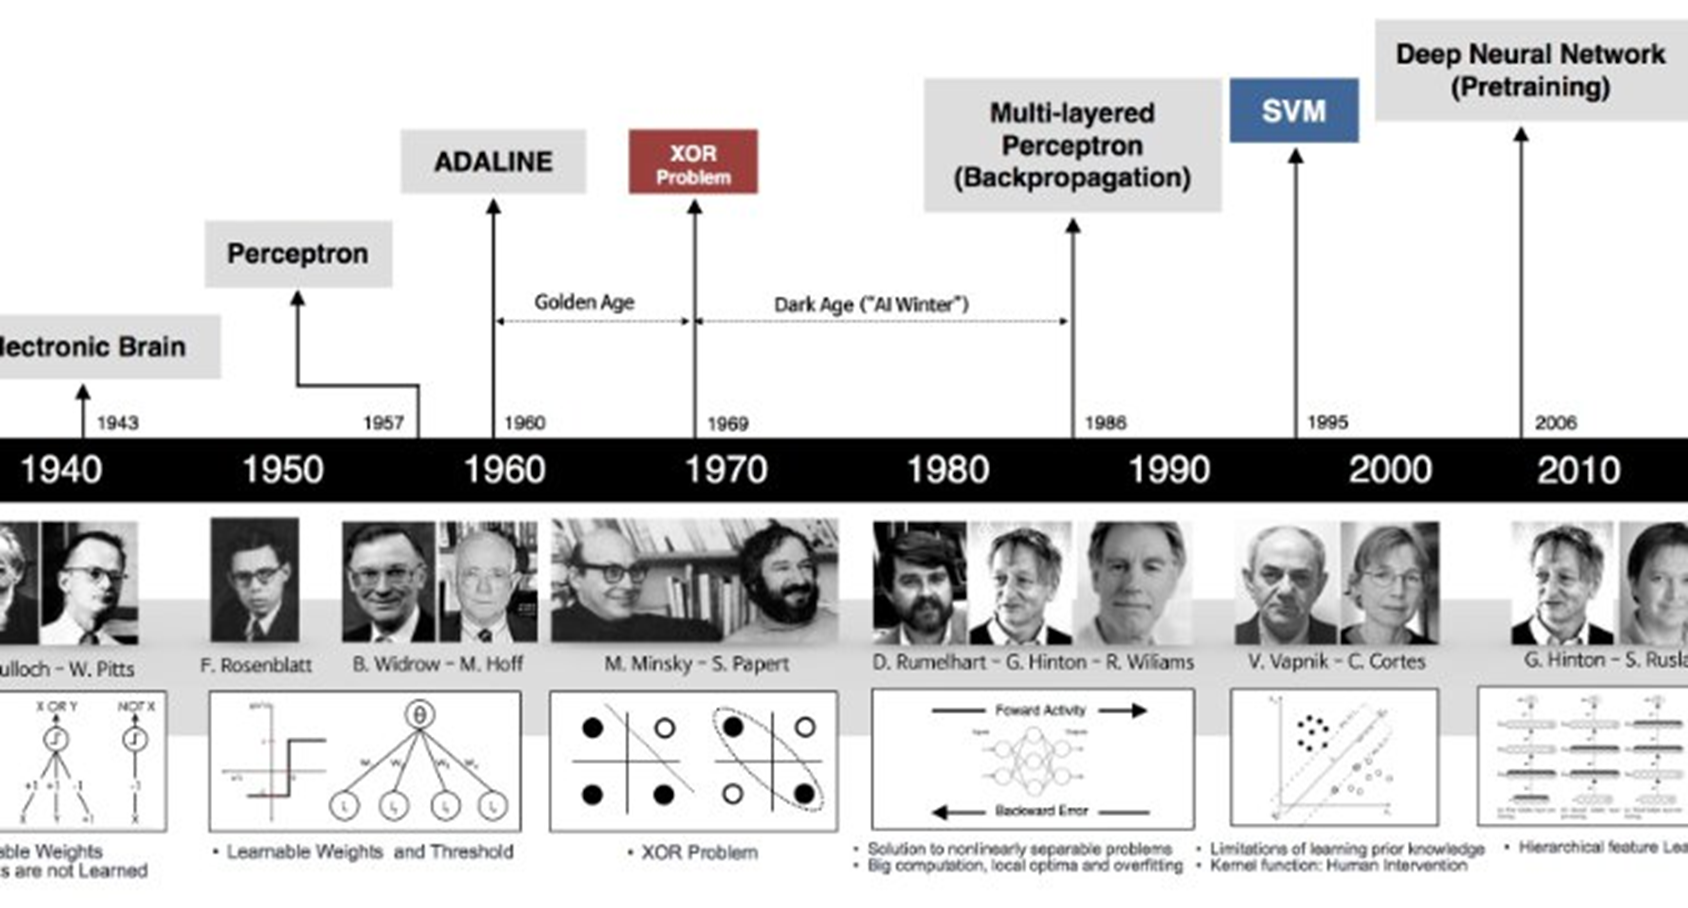

图1 人工智能发展史概览

        一个前向型神经网络的典型拓扑结构如图2所示，包括如下三个组成部分：

- 输入层（第一层）

- 隐含层/隐藏层（第二、三层）

- 输出层（第四层）

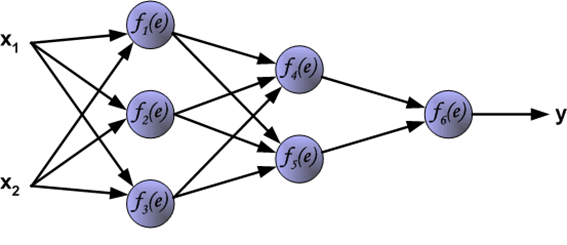

图2 前向型神经网络典型拓扑结构

        **需要说明的是**，在具体代码实现时，通常只需要设计三层结构（即仅包含一层隐含层）即可，因为已有前人证明：若隐含层神经元个数可以无限增加，那么前向型神经网络理论上可以逼近任意非线性关系。

        误差反向传播算法主要包含如下三个阶段：

**        1. 前向传播阶段**

        如图3所示，将训练集样本输入X放置到输入层，前向传播逐层计算隐含层和输出层每个神经元的输出，直至在输出层得到与训练集样本输入X对应的预测值y。

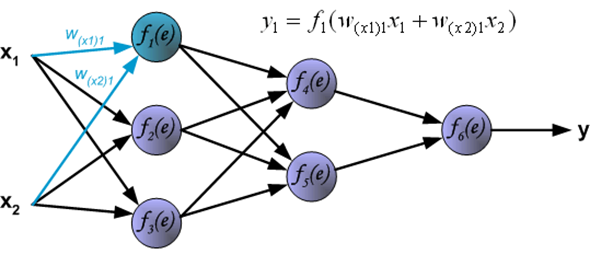

图3 前向传播阶段示意图

        前向型神经网络在最初构建时会随机产生一组连接权值和阈值参数。由于前向型神经网络采用的是全连接方式，即前一层的每个神经元与后一层的每个神经元之间均有连接，因此如图3所示的前向型神经网络的连接权值数量计算如下：

- 输入层与第一隐含层之间：2 × 3 = 6

- 第一隐含层与第二隐含层之间：3 × 2 = 6

- 第二隐含层与输出层之间：2 × 1 = 2

        总计共有6 + 6 + 2 = 14个连接权值。此外，除了输入层外，隐含层和输出层的每个神经元都有一个阈值参数，即如图3所示的前向型神经网络共有3 + 2 + 1 = 6个阈值。因此，该网络中一共有14 + 6 = 20个需要训练调整的参数。      

        在逐层传播的过程中，隐含层和输出层的每个神经元均接收前一层所有神经元传递过来的信号，并与连接权值进行加权和计算。然后，再代入激活函数$y=f\left(\cdot \right)$计算得到该神经元的输出。

        **需要说明的是**，在具体代码实现时，同一层上各个神经元的激活函数均是相同的。

**        2. 反向传播阶段**

        如图4所示，当前向传播阶段完成后，需要计算预测值y与训练集样本输入X对应的真实值z之间的偏差$\delta =y-z$（**在具体代码实现时，通常计算的是误差的平方**），并从输出层向前反向传播，直至传播到第一隐含层。

        **需要说明的是**，注意图4中的虚线部分，与前向传播不同，反向传播的路径并不真实存在，而是经过理论推导后得到一种等价效果，其本质是梯度下降法和链式求导法则。

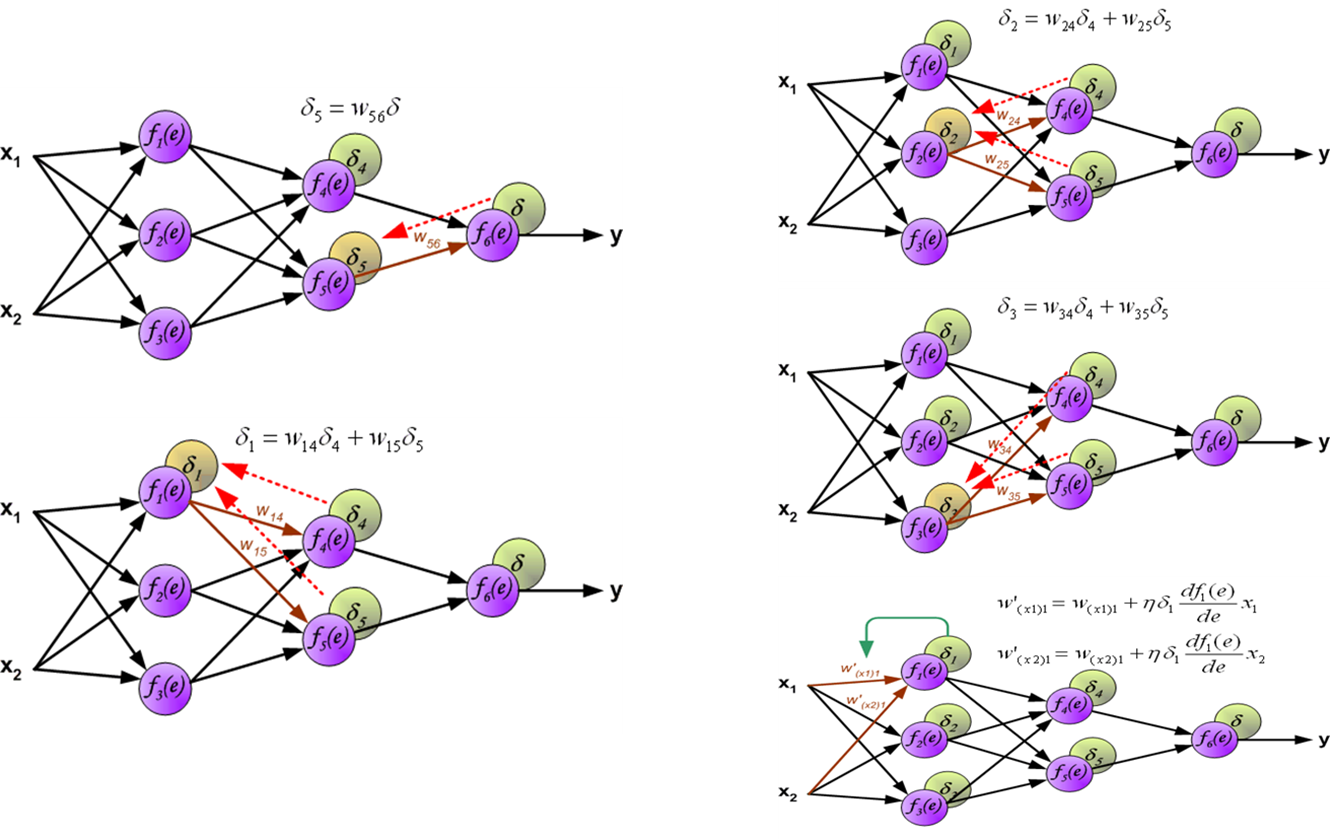

图4 误差反向传播示意图

**        3. 参数修正阶段**

        如图5所示，当反向传播阶段结束后，整个网络中除了输入层外，隐含层和输出层的每个神经元上均有从输出层反向传播过来的误差，利用这些误差，即可对前向型神经网络中的所有参数（连接权值和阈值）进行修正。修正的方式也很简单，即在原参数的基础上加上一个修正项（该修正项可能是正值，也可能是负值）。当修正项＞0时，即意味着增大该参数值；当修正项＜0时，则意味着减小该参数值。

        修正项部分由梯度下降法推导而得，利用该方法对网络中的所有参数进行修正后，可以保证随着多轮迭代的进行，预测值y与训练集样本输入X对应的真实值z之间的偏差$\delta =y-z$可以朝着逐渐减小的方向进行。

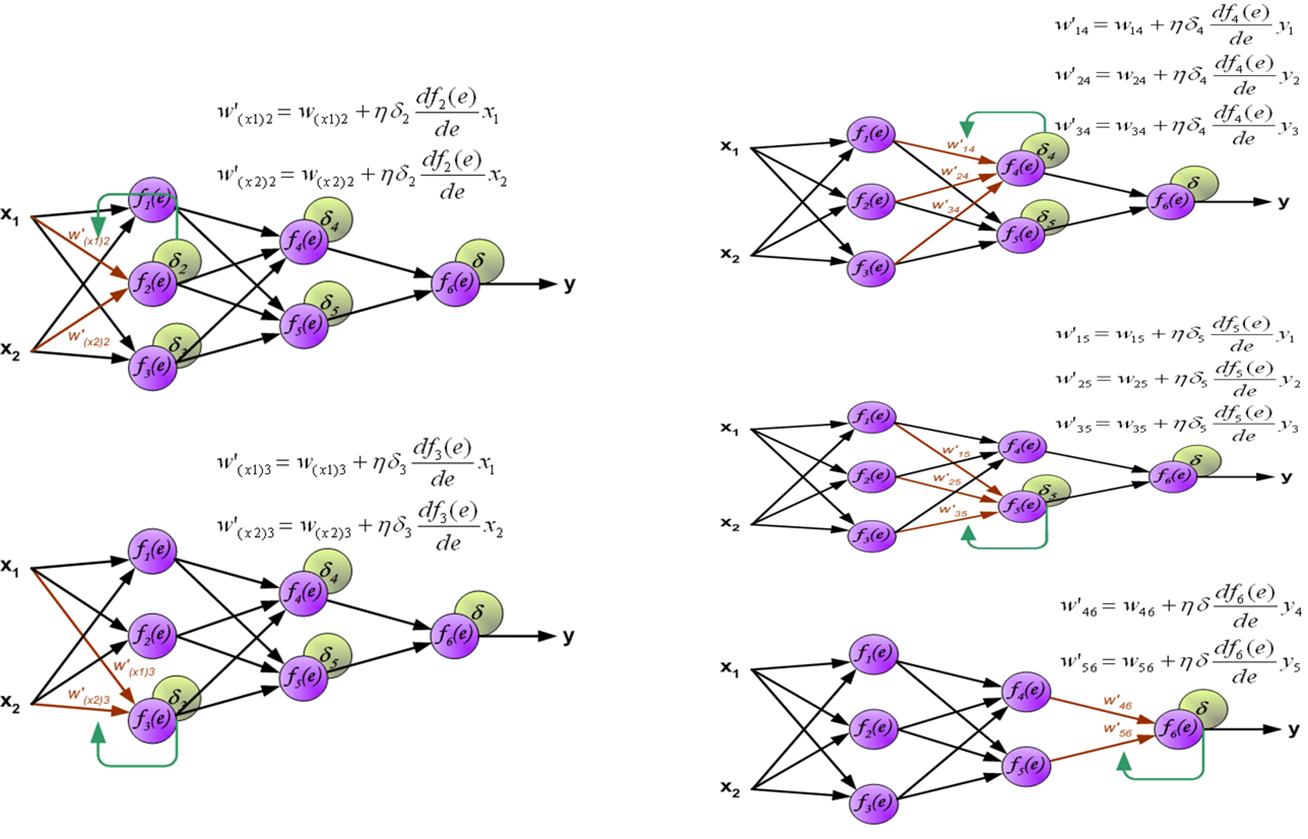     

图5 参数修正示意图

         修正项中存在一个超参数——学习率η（learning rate），该参数对网络训练过程的影响如图6所示。若学习率η较小，则网络参数从初始值修正到最优值需要更多的迭代轮次，即意味着训练时间更长；反之，若学习率η较大，则网络参数的修正过程可能会出现震荡效应，且容易陷入局部极值点。

        **需要说明的是**，在具体代码实现时，可选用固定学习率或自适应学习率两种方式。

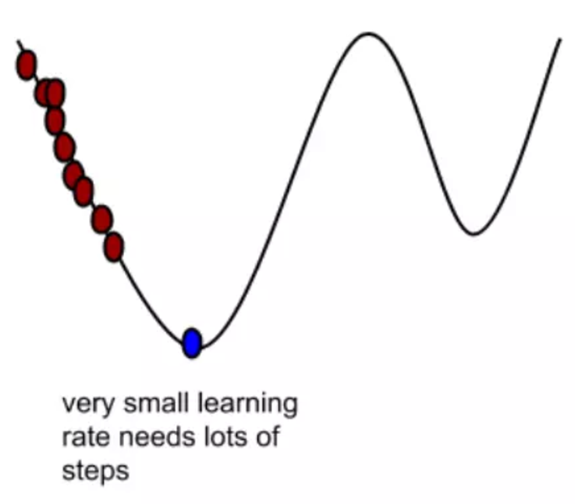    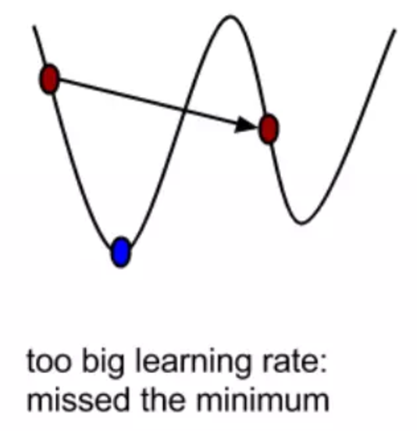

图6 学习率对网络训练过程的影响

### 3.2 案例1：基于BP神经网络的回归拟合——近红外光谱汽油辛烷值预测

- **数据集导入**

        本例使用的数据集为汽油近红外光谱数据集spectra_data.mat，该数据集一共包含60个汽油样品，每个汽油样品均先用波段范围为900-1700nm的近红外光谱仪以2nm为步长的方式扫描得到包含401个波长点的光谱曲线，再用传统实验方法测得其辛烷值含量，即spectra_data.mat中包含两个变量：近红外光谱矩阵NIR (60*401)和辛烷值含量矩阵octane (60*1)。

  load spectra_data.mat

- **训练集/测试集划分**

        不失一般性，这里采用随机法产生训练集和测试集，即随机产生k个样品作为训练集，剩余的60-k个样品作为测试集。

  % 随机产生训练集和测试集
  temp = randperm(size(NIR,1));
  k = 40;
  
  % 训练集：k个样本
  P_train = NIR(temp(1:k),:)';
  T_train = octane(temp(1:k),:)';
  
  % 测试集：60-k个样本
  P_test = NIR(temp(k+1:end),:)';
  T_test = octane(temp(k+1:end),:)';

- **数据归一化**

        数据归一化是数据预处理环节的一个可选步骤，若原始数据不同变量的最大最小值范围之间存在数量级差时（譬如：变量x1的范围是1-10，变量x2的范围是100-10,000），则需要对每个变量进行归一化处理。具体做法是将每个变量从原始范围线性映射到(0, 1)或(-1, 1)范围内，对应的数学公式如下：

$z=\frac{x-x_{\min } }{x_{\max } -x_{\min } }$    或    $z=2\frac{x-x_{\min } }{x_{\max } -x_{\min } }-1$    

        **需要说明的是，**考虑到训练集样本和测试集样本的分布可能不一致，即可能出现测试集样本的最大最小范围比训练集样本的最大最小范围更广的情况，若分别对训练集和测试集单独进行归一化，则可能会出现歧义现象。因此，在实际代码实现时，大多利用训练集的标准对测试集进行归一化。

  % 训练集X归一化
  [p_train, ps_input] = mapminmax(P_train,0,1);
  
  % 利用训练集X归一化的标准对测试集X进行归一化
  p_test = mapminmax('apply',P_test,ps_input);
  
  % 训练集Y归一化
  [t_train, ps_output] = mapminmax(T_train,0,1);

- **BP神经网络创建**

        利用MATLAB神经网络自带工具箱的函数feedforwardnet，可以方便地进行BP神经网络创建。

  % BP神经网络创建
  hiddenNeurous = 10;   % 隐含层神经元个数
  net = feedforwardnet(hiddenNeurous);

- **BP神经网络训练**

        在开始训练之前，可以对相关的训练参数进行设置，也可以采取默认设置。

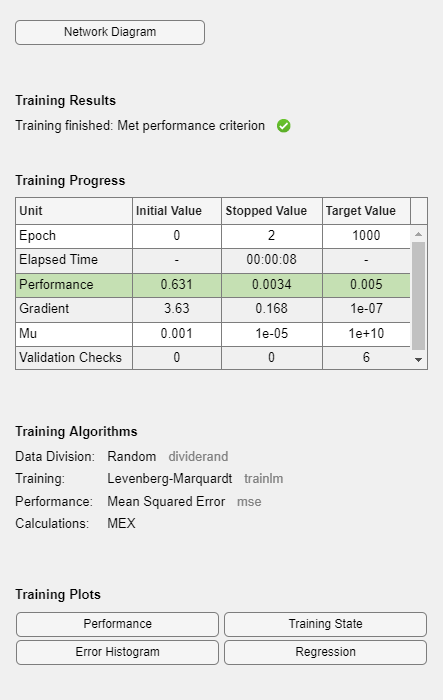

  % 设置训练参数
  net.trainParam.epochs = 1000;    % 最大迭代次数
  net.trainParam.goal = 0.005;      % 训练目标
  net.trainParam.lr = 0.01;        % 学习率
  
  % BP神经网络训练
  net = train(net, p_train, t_train);

- **BP神经网络预测**

        当模型训练好以后，即可将测试集输入p_test送入模型，模型即可计算出相应的预测值。

        **需要说明的是，**若在模型训练前对训练集Y进行了归一化，那么在这里需要对预测值进行反归一化处理。

  % BP神经网络预测
  t_sim = sim(net, p_test);

  % 反归一化处理
  T_sim = mapminmax('reverse', t_sim, ps_output);

- **性能评价**

        当完成模型对测试集样本的预测后，通过计算预测值与真实值的偏差情况，可以对网络的泛化能力进行评价。针对于回归拟合问题而言，常用的评价指标包括：绝对误差、相对误差、均方根误差、决定系数$R^2$等。一般情况下来说，误差越小，决定系数越大，表明模型的泛化性能越高。

  % 绝对误差
  absolute_error = T_sim - T_test

absolute_error =    -1.0543    0.0302   -0.4327   -0.0931   -0.8098   -1.5664   -0.1894    0.7116    0.0842   -2.7303   -0.1833   -0.0017    0.2034   -0.3143    0.8691   -0.2767   -0.1341    0.1075    0.2206    1.1539



  % 相对误差error
  relative_error = abs(T_sim-T_test) ./ T_test

relative_error =     0.0119    0.0003    0.0049    0.0011    0.0095    0.0177    0.0022    0.0081    0.0010    0.0320    0.0022    0.0000    0.0023    0.0036    0.0100    0.0031    0.0015    0.0012    0.0025    0.0131


  % 均方根误差
  rmse = sqrt(mse(T_sim, T_test))

rmse = 0.8613


  % 决定系数R^2  
  N = size(P_test,2);
  R2 = (N * sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ((N * sum((T_sim).^2) - (sum(T_sim))^2) * (N * sum((T_test).^2) - (sum(T_test))^2))

R2 = 0.8175

- **结果绘图可视化**

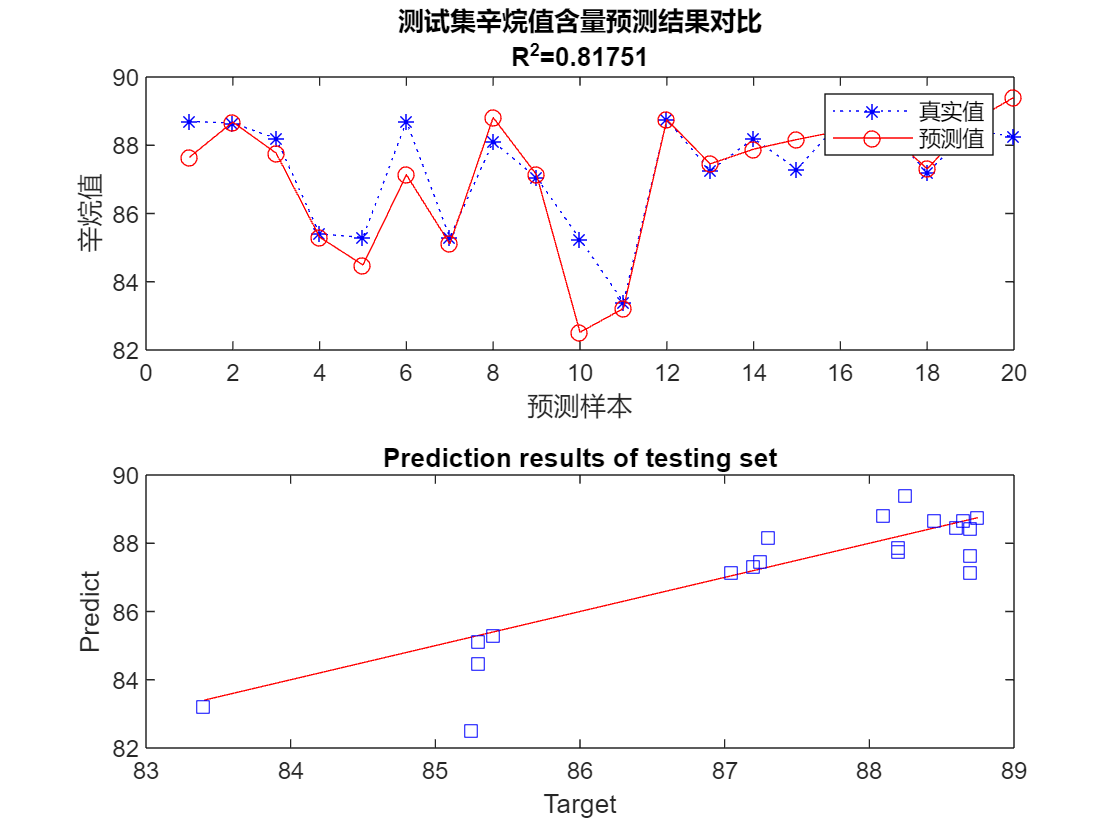

    figure
    subplot(2, 1, 1)
    plot(1:N,T_test,'b:*',1:N,T_sim,'r-o')
    legend('真实值','预测值')
    xlabel('预测样本')
    ylabel('辛烷值')
    string = {'测试集辛烷值含量预测结果对比';['R^2=' num2str(R2)]};
    title(string)

    subplot(2, 1, 2)
    plot(T_test,T_test,'r-')
    hold on
    plot(T_test,T_sim,'bs')
    
    xlabel('Target')
    ylabel('Predict')
    title('Prediction results of testing set')

### **3.3 案例2：基于BP神经网络的分类识别——人脸朝向识别**

- **数据集描述**

        当前工作路径下的Images文件夹中包含10个不同的人分别朝向5个不同的方向时拍摄的共50张照片，本案例拟基于BP神经网络方法建立一个五分类识别模型。

        **注意：**本案例不是建立一个区分不同人的10分类模型，而是区分不同人脸朝向的五分类模型！！！

- **特征提取**

        通过观察不难发现，当人脸朝向不同方向时，人眼在照片中的位置会有所不同。因此，这里提取人眼的特征作为BP神经网络的输入。（类似地，也可以提取鼻子、嘴巴、耳朵等特征作为BP神经网络的输入。）

        提取人眼特征的基本思路如下：

- 对图像进行边缘提取，将灰度图片转换为二值图像；

- 将整张图片沿着竖直的方向（即高度方向）平均分成6块，将第2块（从上往下数）裁剪出来；

- 将第2块沿着水平的方向（即宽度方向）平均分成8块，统计每块中的所有像素值之和。

        经过上述步骤处理后，将从每张图片中提取出一个8维特征向量，最终所有图像经特征提取后将得到一个50×8的二维矩阵。

    M = 10;     % 人数
    N = 5;      % 人脸朝向类别数

    % 特征向量提取
    pixel_value = feature_extraction(M, N);

- **训练集/测试集划分 **

        不失一般性，这里采用随机法产生训练集和测试集，即随机产生k个样品作为训练集，剩余的50-k个样品作为测试集。

        当使用BP神经网络建立分类识别模型时，通常需要进行如下调整：

- 改变输出层神经元的数量，即使得输出层神经元的数量与类别标签数相等；

- 利用ind2vec函数对输出Y进行独特编码（One-hot Encoding）。

    % 产生图像序号的随机序列
    rand_label = randperm(M*N);  
    k = 30;
    
    % 人脸朝向标号
    direction_label = [1;2;3;4;5];

    % 训练集
    train_label = rand_label(1:k);
    P_train = pixel_value(train_label,:)';
    dtrain_label = train_label - floor(train_label/N)*N;
    dtrain_label(dtrain_label == 0) = N;
    t_train = direction_label(dtrain_label,:)';
    T_train = ind2vec(t_train);

    % 测试集
    test_label = rand_label(k+1:end);
    P_test = pixel_value(test_label,:)';
    dtest_label = test_label - floor(test_label/N)*N;
    dtest_label(dtest_label == 0) = N;
    T_test = direction_label(dtest_label,:)';

- **BP神经网络创建**

        利用MATLAB神经网络自带工具箱的函数feedforwardnet，可以方便地进行BP神经网络创建。

% BP神经网络创建
  hiddenNeurous = 10;   % 隐含层神经元个数
  net = feedforwardnet(hiddenNeurous);

- **BP神经网络训练**

        在开始训练之前，可以对相关的训练参数进行设置，也可以采取默认设置。

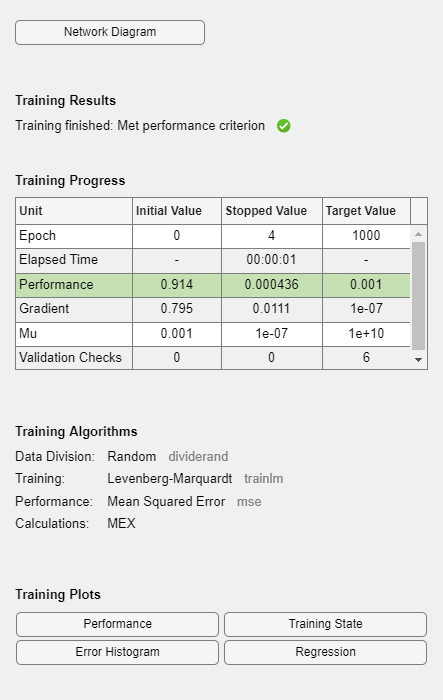

  % 设置训练参数
  net.trainParam.epochs = 1000;    % 最大迭代次数
  net.trainParam.goal = 0.001;      % 训练目标
  net.trainParam.lr = 0.01;        % 学习率
  
  % BP神经网络训练
  net = train(net, P_train, T_train);

- **BP神经网络预测**

        当模型训练好以后，即可将测试集输入P_test送入模型，模型即可预测出相应的类别标签（需要利用vec2ind函数将输出的向量转换为相应的类别标签）。

  % BP神经网络预测
  t_sim = sim(net, P_test);
  T_sim = vec2ind(t_sim)

T_sim =      4     2     1     2     5     5     3     3     1     4     2     2     3     1     2     2     1     5     5     4



  result = [T_sim; T_test]

result =      4     2     1     2     5     5     3     3     1     4     2     2     3     1     2     2     1     5     5     4
     4     2     1     2     5     5     3     3     1     4     2     2     3     1     2     2     1     5     5     4


- **性能评价**

        当完成模型对测试集样本的预测后，通过计算预测值与真实值的偏差情况，可以对网络的泛化能力进行评价。针对于分类识别问题而言，常用的评价指标包括：准确率、精确率、召回率等。一般情况下来说，准确率越高，表明模型的泛化性能越好。

  Accuracy = length(find(T_sim==T_test)) / length(T_test)

Accuracy = 1

### **Appendix：特征提取子函数**

    function pixel_value = feature_extraction(m,n)
        
        pixel_value = zeros(m*n, 8);
        sample_number = 0;
        
        % 遍历每个人
        for i = 1:m
            % 遍历每个朝向
            for j = 1:n
                % 读取图像
                str = strcat('Images\',num2str(i),'_',num2str(j),'.bmp'); 
                img = imread(str);  
                
                % 边缘提取
                img_edge = edge(img,'Sobel');

                % 提取特征
                [rows, cols] = size(img);
                sub_rows = floor(rows/6);
                sub_cols = floor(cols/8);
                sample_number = sample_number + 1;
                for subblock_i = 1:8   
                    for ii = sub_rows+1:2*sub_rows
                        for jj = (subblock_i-1)*sub_cols+1:subblock_i*sub_cols
                            pixel_value(sample_number,subblock_i) = ...
                                pixel_value(sample_number,subblock_i) + img_edge(ii,jj);          
                        end
                    end     
                end  
             end
        end
    end